clear all

HistogramsSpikesTableMUA = load ('D:\Jazmin\MultichannelDataTanks\HIP\Marzo2025\HistogramsSpikesTable_10s_MUA.mat');
HistogramsSpikesTable = load ('D:\Jazmin\MultichannelDataTanks\HIP\Marzo2025\HistogramsSpikesTable_10s.mat'); %The matrix obtained from the fuction ExtractMatFiles.m

SignificanceWindowTableSpikes = [HistogramsSpikesTableMUA.HistogramsSpikesTable;HistogramsSpikesTable.HistogramsSpikesTable];

x1 = SignificanceWindowTableSpikes.histcenters(1,201);
x1_indx = 201;
x2 = SignificanceWindowTableSpikes.histcenters(1,240);
x2_indx = 240;

Path = 'D:\Jazmin\MultichannelDataTanks\HIP\CSI_Boottstrap.xlsx';

% Import table
HIP_Multi  = readtable(Path);
HIParray = table2array(HIP_Multi(:,["CSI","Rango_1","Rango_2"]));
% HIParray(any(isnan(HIParray), 2), :) = [];

load 'D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexesTable_MUA.mat';
load 'D:\Jazmin\MultichannelDataTanks\HIP\\SignificanceWindowTable_MUA.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
load 'D:\Jazmin\MultichannelDataTanks\HIP\\NormalizedIndexesTable.mat';
load 'D:\Jazmin\MultichannelDataTanks\HIP\SignificanceWindowTable.mat';

SignificanceWindowTable = [SignificanceWindowTableMUA;SignificanceWindowTable];
NormalizedIndexesTable = [NormalizedIndexesTableMUA;NormalizedIndexesTable];

% Significance 
n= 1;
for i = 1: size(SignificanceWindowTable,1)
    if (SignificanceWindowTable.SignificanceDEV1(i,1) + SignificanceWindowTable.SignificanceDEV2(i,1)) > 1
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end
end

n=0;
for i = 1:size(SIscatterIndx,1)
    n=n+1;
    HIParrayAuditory(n,[1,2,3]) = HIParray(SIscatterIndx(i),:);
end


n=0;
m=0;
for i = 1:size(HIParrayAuditory,1)
    if HIParrayAuditory(i,2)<0 && HIParrayAuditory(i,3)>0
        n = n + 1;
        NonSignificant(n,1) = i;
    else
        m = m + 1;
        Significant(m,1) = i;
    end
end


for j = 1: size(NonSignificant,1)
    CSI_NonSignificant(j,1) = HIParrayAuditory(NonSignificant(j,1),1);
end

for k = 1: size(Significant,1)
    CSI_Significant(k,1) = HIParrayAuditory(Significant(k,1),1);
end

n=0;
for i = 1:size(SIscatterIndx,1)
    n=n+1;
    SignificanceWindowTableSpikesAuditory(n,:) = SignificanceWindowTableSpikes(SIscatterIndx(i),:);
end

for k = 1: size(Significant,1)
    SignificanceWindowTableSpikesAuditorySig(k,:) = SignificanceWindowTableSpikesAuditory(Significant(k,1),:);
end


for i = 1:size(SignificanceWindowTableSpikesAuditorySig,1)

% STD_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatstd2(i,[41:160]))./2;
% DEV_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,[41:160]))./2;
% CTR_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatctr1ca(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2ca(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatctr1cd(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatctr2cd(i,[41:160]))./4;
% 
% STD_F1_F2_P(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1P(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatstd2P(i,[41:160]))./2;
% DEV_F1_F2_P(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1P(i,[41:160]) + SignificanceWindowTableSpikesAuditorySig.histdatdev2P(i,[41:160]))./2;

STD_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatstd2(i,:))./2;
DEV_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatdev2(i,:))./2;
CTR_F1_F2(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatctr1ca(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatctr2ca(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatctr1cd(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatctr2cd(i,:))./4;

STD_F1_F2_P(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatstd1P(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatstd2P(i,:))./2;
DEV_F1_F2_P(i,:) = (SignificanceWindowTableSpikesAuditorySig.histdatdev1P(i,:) + SignificanceWindowTableSpikesAuditorySig.histdatdev2P(i,:))./2;

N(i,:) = sqrt( (mean(DEV_F1_F2(i,:),"omitnan"))^2 + (mean(STD_F1_F2(i,:),"omitnan"))^2 + (mean(CTR_F1_F2(i,:),"omitnan"))^2);
N_P(i,:) = sqrt( (mean(DEV_F1_F2_P(i,:),"omitnan"))^2 + (mean(STD_F1_F2_P(i,:),"omitnan"))^2 + (mean(CTR_F1_F2(i,:),"omitnan"))^2);

STD_F1_F2(i,:) = STD_F1_F2(i,:)/N(i,:);
DEV_F1_F2(i,:) = DEV_F1_F2(i,:)/N(i,:);
CTR_F1_F2(i,:) = CTR_F1_F2(i,:)/N(i,:);
STD_F1_F2_P(i,:) = STD_F1_F2_P(i,:)/N_P(i,:);
DEV_F1_F2_P(i,:) = DEV_F1_F2_P(i,:)/N_P(i,:);

% histdatstd1Table(i,:) = histdatstd1/max(histdatstd1);
% histdatstd2Table(i,:) = histdatstd2/max(histdatstd2);
% histdatdev1Table(i,:) = histdatdev1/max(histdatdev1);
% histdatdev2Table(i,:) = histdatdev2/max(histdatdev2);
% histdatctr1caTable(i,:) = histdatctr1ca/max(histdatctr1ca);
% histdatctr2caTable(i,:) = histdatctr2ca/max(histdatctr2ca);
% histdatctr1cdTable(i,:) = histdatctr1cd/max(histdatctr1cd);
% histdatctr2cdTable(i,:) = histdatctr2cd/max(histdatctr2cd);
end

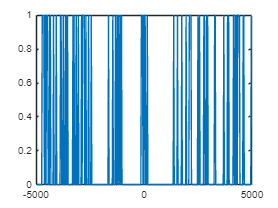

for i = 1:400
    [h(i), p(i)] = ttest2(DEV_F1_F2(:,i),DEV_F1_F2_P(:,i));
end
figure
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,:),h)

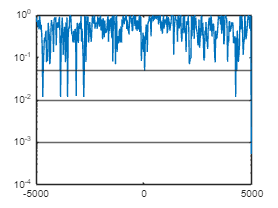

[c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.01);

% plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]),h)
% [c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.01);

% figure
% plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]),h)
% [c_pvalues, c_alpha, h] = fwer_holmbonf(p, 0.05);
% figure
% plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]),h)
%  [c_pvalues, c_alpha, h] = fwer_sidak(p, 0.01);
% figure
% plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]),h)
% [c_pvalues, chi2_2k, h, extra] = mt_fisher(p, 0.05);
% figure
% plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]),h)
% cd 'E:\Jazmin\MultichannelDataTanks\HIP'
% saveas(gcf,'h_R_P.pdf');
figure
% plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]),c_pvalues)
plot(SignificanceWindowTableSpikesAuditorySig.histcenters(1,:),c_pvalues)
% ylim([-0.05 1.05])
yline(0.05)
yline(0.01)
yline(0.001)
set(gca, 'YScale', 'log')

% saveas(gcf,'p_R_P.pdf');

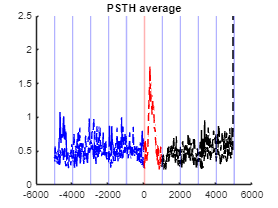

MeanSTD = mean(STD_F1_F2,"omitnan");
MeanDEV = mean(DEV_F1_F2,"omitnan");
MeanCTR = mean(CTR_F1_F2,"omitnan");
MeanSTD_P = mean(STD_F1_F2_P,"omitnan");
MeanDEV_P = mean(DEV_F1_F2_P,"omitnan");

SEM_STD = std(STD_F1_F2,"omitnan")./sqrt(length(STD_F1_F2));
SEM_DEV = std(DEV_F1_F2,"omitnan")./sqrt(length(DEV_F1_F2));
SEM_CTR = std(CTR_F1_F2,"omitnan")./sqrt(length(CTR_F1_F2));
SEM_STD_P = std(STD_F1_F2_P,"omitnan")./sqrt(length(STD_F1_F2_P));
SEM_DEV_P = std(DEV_F1_F2_P,"omitnan")./sqrt(length(DEV_F1_F2_P));

figure
% plot(histcenters, MeanSTD)
% hold on
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]), MeanSTD,SEM_STD,'lineProps','b')

% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:81]), MeanDEV(1,[1:41]),SEM_DEV(1,[1:41]),'lineProps','b')
% hold on
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:121]), MeanDEV(1,[41:81]),SEM_DEV(1,[41:81]),'lineProps','r')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[121:160]), MeanDEV(1,[81:120]),SEM_DEV(1,[81:120]),'lineProps','k')
% % shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]), MeanCTR,SEM_CTR,'lineProps','g')
% % shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]), MeanSTD_P,SEM_STD_P,'lineProps','--b')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:81]), MeanDEV_P(1,[1:41]),SEM_DEV_P(1,[1:41]),'lineProps','--b')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[81:121]), MeanDEV_P(1,[41:81]),SEM_DEV_P(1,[41:81]),'lineProps','--r')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[121:160]), MeanDEV_P(1,[81:120]),SEM_DEV_P(1,[81:120]),'lineProps','--k')

shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[1:200]), MeanDEV(1,[1:200]),SEM_DEV(1,[1:200]),'lineProps','b')
hold on
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[201:240]), MeanDEV(1,[201:240]),SEM_DEV(1,[201:240]),'lineProps','r')
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[241:end]), MeanDEV(1,[241:end]),SEM_DEV(1,[241:end]),'lineProps','k')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]), MeanCTR,SEM_CTR,'lineProps','g')
% shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[41:160]), MeanSTD_P,SEM_STD_P,'lineProps','--b')
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[1:200]), MeanDEV_P(1,[1:200]),SEM_DEV_P(1,[1:200]),'lineProps','--b')
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[201:240]), MeanDEV_P(1,[201:240]),SEM_DEV_P(1,[201:240]),'lineProps','--r')
shadedErrorBar(SignificanceWindowTableSpikesAuditorySig.histcenters(1,[241:end]), MeanDEV_P(1,[241:end]),SEM_DEV_P(1,[241:end]),'lineProps','--k')
ylim([0 2.5])

patch([-5000,-4925,-4925,-5000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([-4000,-3925,-3925,-4000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([-3000,-2925,-2925,-3000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([-2000,-1925,-1925,-2000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')

patch([-1000,-925,-925,-1000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
% xline(-1000)
% xline(-925)

% xline(0)
% xline(75)
patch([0,75,75,0],[0,0,2.5,2.5],'red','FaceAlpha',.3,'LineStyle','none')
% xline(1000)
% xline(1075)
patch([1000,1075,1075,1000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([5000,5075,5075,5000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([4000,4075,4075,4000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([3000,3075,3075,3000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')
patch([2000,2075,2075,2000],[0,0,2.5,2.5],'blue','FaceAlpha',.3,'LineStyle','none')

title('PSTH average')


cd 'D:\Jazmin\MultichannelDataTanks\HIP\Marzo2025'
saveas(gcf,'Gran_Average_longer_R_P.pdf');
saveas(gcf,'Gran_Average_longer_R_P.tif');

saveas(gcf,'Gran_Average_longer_R_P.fig');

% cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1';
% save('NormalizedIndexesTaar
% le.mat', 'NormalizedIndexesTable');

% MMN = MeanDEV - MeanSTD;
% for i = 1:size(SEM_STD,2)
% SEM_MMN(1,i) = sqrt( (SEM_STD(1,i))^2 + (SEM_DEV(1,i))^2);
% end
% figure
% shadedErrorBar(SignificanceWindowTable.histcenters(1,[81:120]), MMN,SEM_MMN,'lineProps','k')
% ylim([-1 1])
% title('CA1 Mismatch')